% Start defaults (assuming this is a script/function that sets up the environment)
mystartdefaults
num_method_final

discrete_bound1 =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000   15.0000


discrete_bound2 =    65.0000   65.5000   66.0000   66.5000   67.0000   67.5000   68.0000   68.5000   69.0000   69.5000   70.0000   70.5000   71.0000   71.5000   72.0000   72.5000   73.0000   73.5000   74.0000   74.5000   75.0000   75.5000   76.0000   76.5000   77.0000   77.5000   78.0000   78.5000   79.0000   79.5000   80.0000


Lower energy bound (Ea) = 0.000000 eV
Upper energy bound (Eb) = 150.411749 eV


discrete_bound1 =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000   15.0000


discrete_bound2 =    65.0000   65.5000   66.0000   66.5000   67.0000   67.5000   68.0000   68.5000   69.0000   69.5000   70.0000   70.5000   71.0000   71.5000   72.0000   72.5000   73.0000   73.5000   74.0000   74.5000   75.0000   75.5000   76.0000   76.5000   77.0000   77.5000   78.0000   78.5000   79.0000   79.5000   80.0000


Lower energy bound (Ea) = 0.000000 eV
Upper energy bound (Eb) = 150.411749 eV


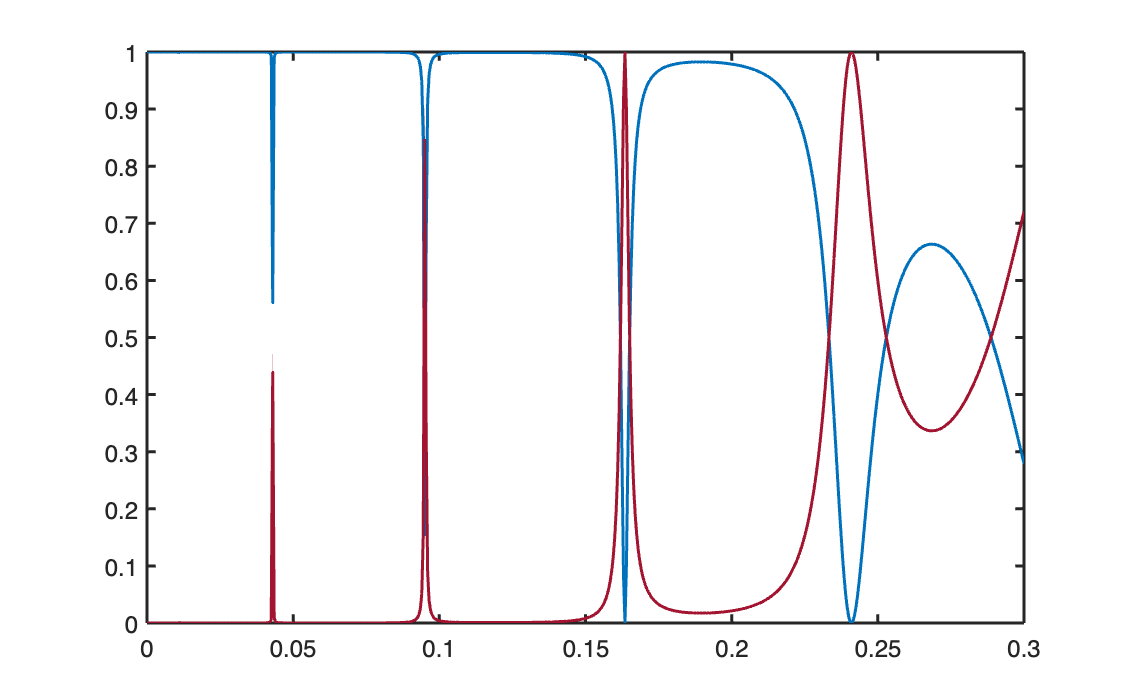

question_2

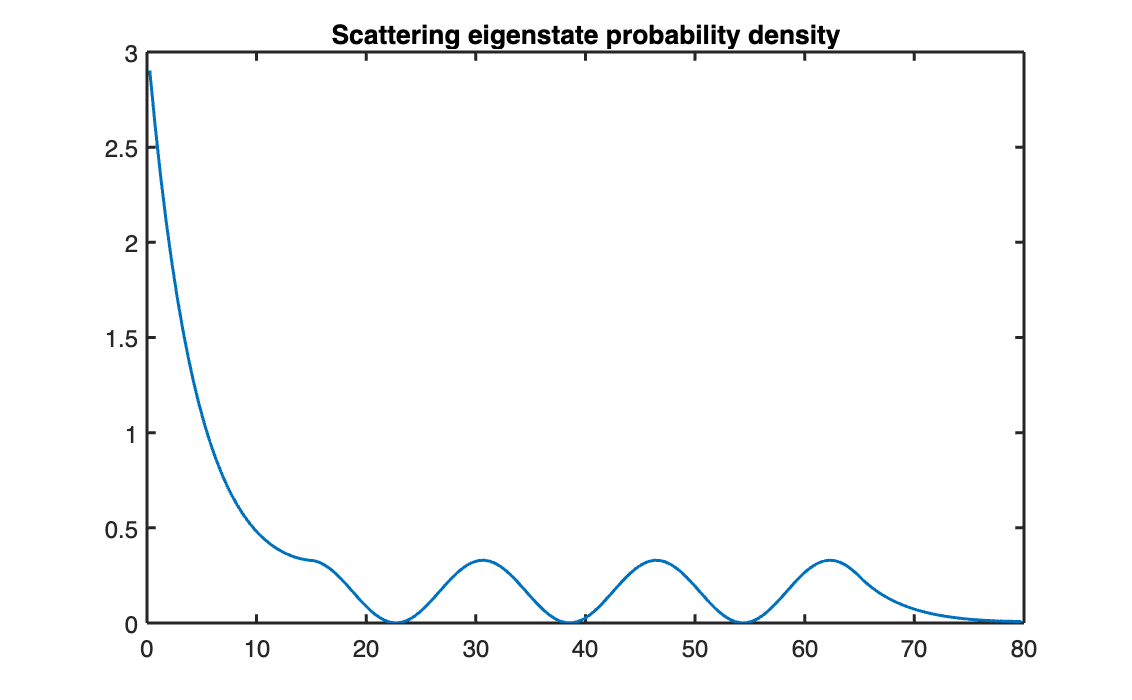

% Get default figure position from MATLAB graphics root
pos = get(groot,'DefaultFigurePosition');

% Start timing
tic;

% Declaring units
recipunit = 1.0E+10;
hbar = 1.0545718e-34; % Planck's constant over 2pi
elm = 9.10938356e-31; % Electron mass
qel = 1.602176634e-19; % Elementary charge
ekinscale = ((hbar*recipunit)^2/(2*elm))/qel;

% Energy E0
E0_min = 0;
E0_max = 0.3;
l = 5;
estep = 0.1;
E0 = repmat(0.15, 1, l);

% Space Discretization inside potentials

% Inside U1

step_size = 0.5;
x1_min = 0;
x1_max = 80;

n = (x1_max - x1_min)/step_size;

U = zeros(n,1); % Potential barriers
x1 = linspace(x1_min + step_size/2, x1_max - step_size/2, n).';

for i = 1:n
    if x1(i) <= 15
        U(i) = 0.2;
    elseif x1(i) >= 65 && x1(i) <= 80
        U(i) = 0.2;
    else
        U(i) = 0;
    end
    V(i) = U(i)/ekinscale;
end

% Space discretization
x_min = -20;
x_max = 100;
m = floor((x_max-x_min)/step_size);
x = linspace(x_min + step_size/2, x_max - step_size/2, m).';

% Defining parameters
k = sqrt(E0./ekinscale);
lambda = 2*pi./k;

% Plane wave inside potentials
phi1 = arrayfun(@(k) exp(1i*k*x1), k, 'UniformOutput', false);

% Greens function
G1 = arrayfun(@(k) step_size * exp(1i*k*abs(x1 - x1'))/(2*1i*k), k, 'UniformOutput', false);

% Scattering matrix and scattering eigenfunction inside perturbation
T1 = cell(1, l);
Phip1 = cell(1, l);
for i = 1:l
    T1{i} = eye(n) - G1{i}.*V;
    Phip1{i} = T1{i} \ phi1{i};
end

% Plotting
figure;
plot(x1, abs(Phip1{3}).^2);
title('Scattering eigenstate probability density');

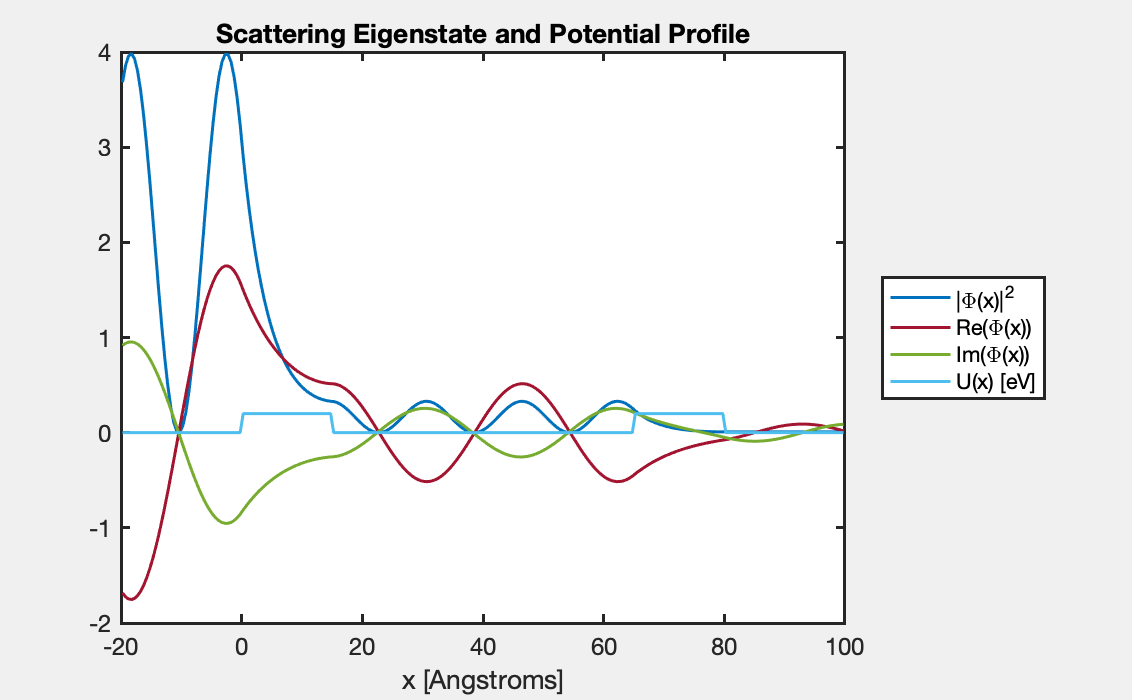


% Working outside potential: To find phi scattered
Phis = cell(1, l);
Phi = cell(1, l);
Prob = cell(1, l);
for i = 1:l
    Phis{i} = zeros(m, 1);
    Phi{i} = zeros(m, 1);
    Prob{i} = zeros(m, 1);
    for j = 1:m
        for h = 1:n
            Phis{i}(j) = Phis{i}(j) + step_size * exp(1i*k(i)*abs(x(j) - x1(h)))/(2*1i*k(i)) * V(h) * Phip1{i}(h);
        end
        Phi{i}(j) = exp(1i*k(i)*x(j)) + Phis{i}(j);
        Prob{i}(j) = abs(Phi{i}(j))^2;
    end
end

% Spectrum
Ugraph = zeros(m, 1);
for i = 1:m
    if x(i) >= x1_min && x(i) <= 15
        Ugraph(i) = 0.2;
    elseif x(i) > 65 && x(i) <= x1_max
        Ugraph(i) = 0.2;
    end
end

figure('Visible', 'on', 'NumberTitle', 'off', 'Name', 'Scattering eigenstate');
plot(x, Prob{3}); hold on;
plot(x, real(Phi{3})); hold on;
plot(x, imag(Phi{1})); hold on;
plot(x, Ugraph);
xlabel('x [Angstroms]');
legend('|\Phi(x)|^2', 'Re(\Phi(x))', 'Im(\Phi(x))', 'U(x) [eV]', 'Location', 'eastoutside');
title('Scattering Eigenstate and Potential Profile');

asdf

% Check the lengths of E0 and T_values
fprintf('Length of E0: %d\n', length(E0));

Length of E0: 5


fprintf('Length of T_values: %d\n', length(T_values));

Length of T_values: 601



% Initialize an array to hold the indices of resonant energies
resonant_indices = [];

% Loop through the T_values array to find peaks
for i = 2:length(T_values)-1
    if T_values(i) > T_values(i-1) && T_values(i) > T_values(i+1)
        % A simple check for a local maximum
        resonant_indices = [resonant_indices, i];
    end
end

% Add a check to see if resonant_indices is empty
if isempty(resonant_indices)
    fprintf('No resonant indices found.\n');
else
    % Extract the resonant energies using the indices
    resonant_energies = E0(resonant_indices);

    % Plot to verify the peaks
    plot(E0, T_values);
    hold on;
    plot(E0(resonant_indices), T_values(resonant_indices), 'r*', 'MarkerSize', 10);
    title('Transmission Coefficients with Identified Peaks');
    xlabel('Energy (E0)');
    ylabel('Transmission Coefficient (T)');
    legend('T(E0)', 'Identified Peaks');
    hold off;
end

Index exceeds the number of array elements. Index must not exceed 5.